% Author: Kenneth H.L. Ho
% Copyright 2019 RIKEN BDR
% License: GPL v3 https://www.gnu.org/licenses/gpl-3.0.txt 

## Accessing images directly from SSBD database into MATLAB

% Access SSBD and retrieve image id = 340, Z = 30, t = 0
img = ssbd.image(34073, 0, 0); 

id: 34073, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34073/0/0


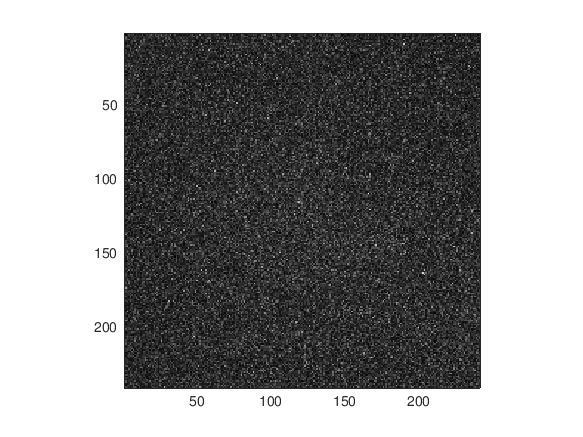

image(img)
daspect([1,1,1]);

img2 = ssbd.image(34074, 0, 0);

id: 34074, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34074/0/0


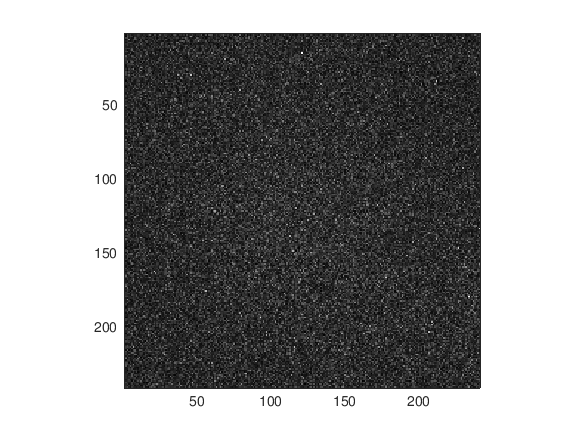

imagesc(img2)
daspect([1,1,1])

img21 = rgb2gray(img2);

img3 = rgb2gray(ssbd.image(34075, 0, 0));

id: 34075, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34075/0/0


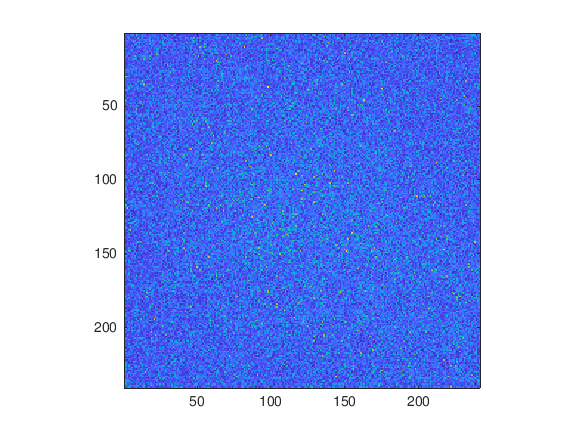

imagesc(img3);
daspect([1,1,1]);

% Bashar images in SSBD starting with image_id = 34073.
% it has 28 stacks.
% Reading in Bashar slices and convert them into a 4D image stack.
img_id = 34073;
img = [];
imgt =[];
for t = 1:5
    for i = 1:28
        img{i} = rgb2gray(ssbd.image(img_id, 0, 0));
        whos img;
        img_id=img_id+1;
    end
        imgt{t} = cat(3, img{:});
end

id: 34073, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34073/0/0


  Name      Size            Bytes  Class    Attributes

  img       1x1             58193  cell               



id: 34074, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34074/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x2             116386  cell               



id: 34075, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34075/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x3             174579  cell               



id: 34076, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34076/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x4             232772  cell               



id: 34077, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34077/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x5             290965  cell               



id: 34078, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34078/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x6             349158  cell               



id: 34079, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34079/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x7             407351  cell               



id: 34080, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34080/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x8             465544  cell               



id: 34081, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34081/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x9             523737  cell               



id: 34082, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34082/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x10            581930  cell               



id: 34083, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34083/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x11            640123  cell               



id: 34084, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34084/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x12            698316  cell               



id: 34085, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34085/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x13            756509  cell               



id: 34086, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34086/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x14            814702  cell               



id: 34087, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34087/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x15            872895  cell               



id: 34088, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34088/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x16            931088  cell               



id: 34089, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34089/0/0


  Name      Size             Bytes  Class    Attributes

  img       1x17            989281  cell               



id: 34090, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34090/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x18            1047474  cell               



id: 34091, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34091/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x19            1105667  cell               



id: 34092, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34092/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x20            1163860  cell               



id: 34093, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34093/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x21            1222053  cell               



id: 34094, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34094/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x22            1280246  cell               



id: 34095, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34095/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x23            1338439  cell               



id: 34096, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34096/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x24            1396632  cell               



id: 34097, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34097/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x25            1454825  cell               



id: 34098, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34098/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x26            1513018  cell               



id: 34099, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34099/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x27            1571211  cell               



id: 34100, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34100/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34101, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34101/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34102, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34102/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34103, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34103/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34104, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34104/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34105, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34105/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34106, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34106/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34107, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34107/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34108, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34108/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34109, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34109/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34110, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34110/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34111, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34111/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34112, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34112/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34113, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34113/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34114, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34114/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34115, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34115/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34116, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34116/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34117, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34117/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34118, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34118/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34119, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34119/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34120, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34120/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34121, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34121/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34122, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34122/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34123, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34123/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34124, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34124/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34125, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34125/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34126, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34126/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34127, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34127/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34128, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34128/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34129, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34129/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34130, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34130/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34131, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34131/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34132, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34132/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34133, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34133/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34134, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34134/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34135, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34135/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34136, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34136/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34137, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34137/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34138, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34138/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34139, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34139/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34140, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34140/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34141, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34141/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34142, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34142/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34143, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34143/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34144, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34144/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34145, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34145/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34146, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34146/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34147, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34147/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34148, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34148/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34149, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34149/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34150, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34150/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34151, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34151/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34152, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34152/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34153, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34153/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34154, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34154/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34155, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34155/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34156, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34156/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34157, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34157/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34158, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34158/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34159, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34159/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34160, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34160/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34161, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34161/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34162, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34162/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34163, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34163/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34164, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34164/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34165, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34165/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34166, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34166/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34167, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34167/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34168, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34168/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34169, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34169/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34170, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34170/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34171, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34171/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34172, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34172/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34173, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34173/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34174, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34174/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34175, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34175/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34176, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34176/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34177, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34177/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34178, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34178/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34179, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34179/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34180, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34180/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34181, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34181/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34182, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34182/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34183, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34183/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34184, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34184/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34185, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34185/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34186, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34186/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34187, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34187/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34188, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34188/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34189, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34189/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34190, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34190/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34191, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34191/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34192, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34192/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34193, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34193/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34194, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34194/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34195, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34195/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34196, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34196/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34197, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34197/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34198, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34198/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34199, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34199/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34200, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34200/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34201, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34201/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34202, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34202/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34203, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34203/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34204, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34204/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34205, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34205/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34206, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34206/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34207, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34207/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34208, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34208/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34209, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34209/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34210, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34210/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34211, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34211/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



id: 34212, z: 0, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/34212/0/0


  Name      Size              Bytes  Class    Attributes

  img       1x28            1629404  cell               



imgzt = cat(4, imgt{:});
    

whos imgzt

  Name         Size                    Bytes  Class    Attributes

  imgzt      241x241x28x5            8131340  uint8              



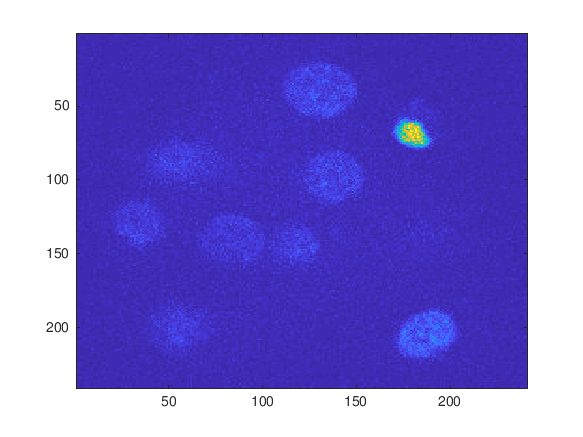

% display the image z = 14 and t = 3
imagesc(imgzt(:,:,14,3));